Calculando o Tau e o Kcc

opts = detectImportOptions('dados_aquecedor_matlab.csv');
T = readtable('dados_aquecedor_matlab.csv', opts);

% Achando tau e o ganho Kcc
stable_temperature = 26.0;
aux_temp = stable_temperature * 0.632;
[~, idx] = min(abs(temp_offset - aux_temp));
tau = time(idx);
Kcc = stable_temperature/0.015;
disp(['Tau: ', num2str(tau)]);

Tau: 930


disp(['Kcc: ', num2str(Kcc)]);

Kcc: 1733.3333


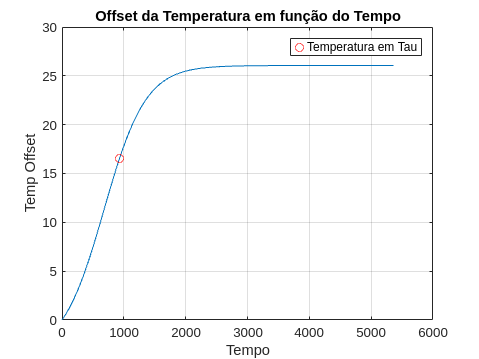


time = T.time;
temp_offset = T.temp_offset;
plot(time, temp_offset);
hold on;
temp_offset_at_tau = temp_offset(idx);
plot(tau, temp_offset_at_tau, 'ro'); % Destacar o ponto
title('Offset da Temperatura em função do Tempo');
legend('', 'Temperatura em Tau');
xlabel('Tempo');
ylabel('Temp Offset');
grid on;
hold off;

Achando a função de transferencia

s = tf('s');
G = Kcc / (tau*s + 1)


G =
 
    1733
  ---------
  930 s + 1
 
Continuous-time transfer function.
Model Properties
